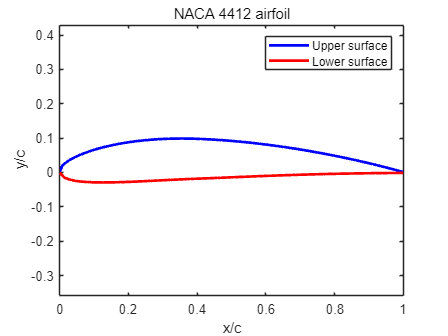

% VortexPanelMethod.m
% This script uses the Vortex Panel Method to calculate the pressure coefficient of NACA 4412 airfoil
clear all;

%% Load airfoil coordinates
run('AirfoilNACA4412.m');

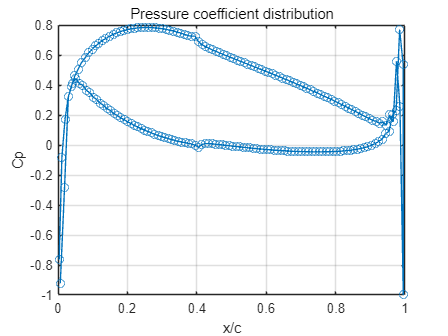


%% Combine coordinates of the upper and lower surfaces
x_airfoil = [xu(1:end-1),flip(xl(1:end))]'; % Combine upper and lower surfaces
y_airfoil = [yu(1:end-1),flip(yl(1:end))]';

%% Panel method setup
N = length(x_airfoil)-1; % Number of panels
panels = zeros(N, 4);
panels(:,1) = (x_airfoil(1:end-1)+x_airfoil(2:end)) ./ 2;
panels(:,2) = (y_airfoil(1:end-1)+y_airfoil(2:end)) ./ 2; % Control points
panels(:,3) = sqrt((x_airfoil(1:end-1)-x_airfoil(2:end)).^2 + (y_airfoil(1:end-1)-y_airfoil(2:end)).^2); % Panel lengths
panels(:,4) = atan((y_airfoil(1:end-1)-y_airfoil(2:end))./(x_airfoil(1:end-1)-x_airfoil(2:end))); % Panel angles

x_con = panels(:,1)'; % Control point x-coordinates
y_con = panels(:,2)'; % Control point y-coordinates

J = (1 + ((panels(:,2)-y_con)./(panels(:,1)-x_con)).^2).^(-1) .* ...
    (sin(panels(:,4)).*(panels(:,2)-y_con)./(panels(:,1)-x_con).^2 + ...
    cos(panels(:,4)).*(panels(:,1)-x_con).^(-1)); % Directional derivatives
A = J .* (panels(:,3))'; % Coefficient matrix for the system of equations
A(isnan(A)) = 0;
Simpson = zeros(N,N);
for i = 1:N
    if i == 1
        Simpson(i,i) = 4/6;
        Simpson(i,i+1) = 1/6;
        Simpson(i,N) = 1/6;
    elseif i == N
        Simpson(i,i) = 4/6;
        Simpson(i,i-1) = 1/6;
        Simpson(i,1) = 1/6;
    else
        Simpson(i,i) = 4/6;
        Simpson(i,i-1) = 1/6;
        Simpson(i,i+1) = 1/6;
    end
end

%% Free stream velocity
V_inf = 10;
alpha = 0; % Angle of attack in degrees
alpha_rad = deg2rad(alpha);

b = V_inf .* cos(pi/2 - (panels(:,4) - alpha_rad)) .* (2 * pi); % Free stream velocity vector

b(round(N/2),:) = 0; % Last panel velocity is zero
A(round(N/2),:) = zeros(1,N);
A(round(N/2),round(N/2):round(N/2)+1) = [1,1];
%A = A * Simpson;
gamma = A \ b; % Solve for circulation strengths

Gamma = zeros(N,1);
Gamma(1:end-1) = (gamma(1:end-1)+gamma(2:end))./2;
Gamma(end) = (gamma(end)+gamma(1))/2;
Gamma = Simpson*Gamma;
%% Calculate velocity diistribution
V = -1 .* Gamma;

%% Calculate pressure coefficient
Cp = 1 - (V/V_inf).^2;

%% Plot results
figure;
plot(x_con, -Cp, 'o-');
xlabel('x/c');
ylabel('Cp');
title('Pressure coefficient distribution');
grid on;